# Paramètres

% Nombre de sous domaine
ns = 6;
% Nombre d'éléments par sous domaine
ne = 3;
% Longueur de la barre
L = 0.1;             % m
S = 10 * 10^(-4);    % m2
E = 2*10^11;         % Pa
Fd = 10;             % N
% Conditions aux limites
Ud0 = 0;
FdL = Fd;



## Initialisation


H = L / ns;   % longueur de chaque sous domaine
h = H / ne;     % longueur d'un élément
ne_t = ne * ns;    % nombre d'élément total
nn_t = ne*ns +1;  % nombre de noeuds total
nn = ne + 1;     % nombre de noeuds par sous-domaine

F=zeros(nn,ns);
F(nn,ns) = FdL; %force appliquée sur le dernier ddl

% Variable noeuds
nodes = 1:nn_t;    
% Tableau de connectivité global
subdomains = zeros(2,ne_t);
for el = 1:ne_t
    subdomains(1,el) = nodes(el);
    subdomains(2,el) = nodes(el+1);
end
% Tableau de connectivité local
elements = zeros(2,ne_t);
for sd = 1:ns
    for e = 1:ne
        el = (sd-1)*ne + e;  % indice de l'élément
        elements(1,el) = nodes(el) - (nn-1) * (sd-1);
        elements(2,el) = nodes(el+1) - (nn-1) * (sd-1);
    end
end

## Calcul matrice de rigidité

K = zeros(ne+1,ne+1,ns); % Matrice de rigitité global
Ke = zeros(2,2,ne_t);   % Matrice de rigidité locale

% Matrice de rigidité de chaque élément
for el = 1:ne_t
    Ke(1,1,el) = S*E/h * 1;
    Ke(1,2,el) = S*E/h * (-1);
    Ke(2,1,el) = S*E/h * (-1);
    Ke(2,2,el) = S*E/h * 1;
end

% Matrice de rigidité de chaque sous domaine
for sd = 1:ns
    for e = 1:ne
        el = (sd-1)*ne + e;  % indice de l'élément
        K(elements(1,e),elements(1,e),sd) = K(elements(1,e),elements(1,e),sd) + Ke(1,1,e);
        K(elements(1,e),elements(2,e),sd) = K(elements(1,e),elements(2,e),sd) + Ke(1,2,e);
        K(elements(2,e),elements(1,e),sd) = K(elements(2,e),elements(1,e),sd) + Ke(2,1,e);
        K(elements(2,e),elements(2,e),sd) = K(elements(2,e),elements(2,e),sd) + Ke(2,2,e);

    end
end

## Méthode direct

%% Analytique (référence)

node = 1:24;
U_ref = direct_analytique(L,node,Fd,E,S);


if ns == 1  % A corriger (cf. à faire)
    
    %% Méthode par substitution
    U_subst = direct_substitution(ns,nn,K,F);
    
    %% Méthode par pénalité
    K_pen = K;
    F_pen = F;
    g = 2*10^18; % tester plusieurs valeurs
    U_pen = direct_penalite(ns,nn,K_pen,F_pen,g,Ud0);
    
    %% Méthode lagrangien
    % L(u,lambda) = 1/2ku² - lambda(u - u_d)
    % on a une valeur lambda en plus

end

## Interface Schur primal and dual

% Initialisation
n_bord = ns*2 - 2;  % nombre de bord
ni = ns - 1;        % nombre d'interface skeleton
% Operateurs 
Sp_conc = sparse(n_bord,n_bord);
Sd_conc = sparse(n_bord,n_bord);
Ap_conc = zeros(ni,n_bord);
Ad_conc = zeros(ni,n_bord);
bp_conc = zeros(n_bord,1);
Rb_conc = sparse(n_bord,ns-1); % (ns-1) parce que le premier sd n'a pas de Rb
for sd = 1:ns
    if sd == 1  % encastrement -> i
        % Méthode par substitution
        i = 2:nn-1;     % on substitue ligne et colonne de u1
        b = nn;

        index_sp = 1;
        index_a = 1;
        index_rx = 1;
        index_ry = 1;
        Ap = [1;0];
        Ad = [1;0];
    elseif sd == ns % noeud libre -> i
        i = 2:nn;
        b = 1;

        index_sp = n_bord;
        index_rx = index_rx + size(Rb,1);
        index_ry = index_ry + size(Rb,2);
        Ap = [0;1];
        Ad = [0;-1];
    else
        i = 2:nn-1;
        b = [1,nn];

        index_sp = 2 * (sd - 1);
        index_a = sd-1;
        index_rx = index_rx + size(Rb,1);
        index_ry = index_ry + size(Rb,2);
        Ap = [1,0;0,1];
        Ad = [-1,0;0,1];
    end

    
    Sp = K(b,b,sd) - K(b,i,sd) * ( K(i,i,sd) \ K(i,b,sd) );     % primal schur complement
    Rb = null(Sp);                                                  % Rigid body mode
    Sd = pinv(Sp);                                                  % dual schur complement
    bp = F(b,sd) - K(b,i,sd) * ( K(i,i,sd) \ F(i,sd) );           % primal right-hand side
     

    % Concatenation
    Sp_conc(index_sp:index_sp+size(b,2)-1,index_sp:index_sp+size(b,2)-1) = Sp;  % primal schur concatenated
    Ap_conc(index_a:index_a+1,index_sp:index_sp+size(Ap,2)-1) = Ap;               % primal assembly operator concatenated
    bp_conc(index_sp:index_sp+size(bp,1)-1,1) = bp;                             % primal right hand side concatenated
    Sd_conc(index_sp:index_sp+size(b,2)-1,index_sp:index_sp+size(b,2)-1) = Sd;  % dual schur concatenated
    Ad_conc(index_a:index_a+1,index_sp:index_sp+size(Ad,2)-1) = Ad;               % dual assembly operator concatenated
    Rb_conc(index_rx:index_rx+size(Rb,1)-1,index_ry:index_ry+size(Rb,2)-1) = Rb;
end 



## Primal approach

% Assembled operators
Sp_ass = Ap_conc * Sp_conc * Ap_conc';
bp_ass = Ap_conc * bp_conc;

%% Direct method
U_primal_direct = primal_direct(ns,nn,Sp_ass,bp_ass,Ap_conc,K,F);

%% Iterative method
tol = 1e-10;
U_primal_distrib = primal_distributed(ns,nn,Ap_conc,K,F,tol);

   10.0000

   10.0000

   10.0000

   10.0000

   2.4921e-14

5 iterations



%u_conjgrad = conjgrad(Sp_ass,bp_ass,tol);
u_pcg = pcg(Sp_ass,bp_ass,tol);

pcg converged at iteration 5 to a solution with relative residual 0.


u_cg = conjugate_gradient(Sp_ass,bp_ass);

4 iterations


u_prec_cg = prec_conjugate_gradient(Sp_ass,bp_ass);

3 iterations


## Dual approach

% Assembled operators
bd_conc = Sd_conc * bp_conc;
Sd_ass = Ad_conc * Sd_conc * Ad_conc';
bd_ass = Ad_conc * bd_conc;
G_ass = Ad_conc * Rb_conc;
e_conc = Rb_conc' * bp_conc;

% Direct method
tmp = [Sd_ass,G_ass;G_ass',zeros(size(G_ass',1),size(G_ass,2))] \ [-bd_ass;-e_conc];
lb_ass = tmp(1:size(bd_ass,1),1);
alb_conc = tmp(size(lb_ass,1)+1:end,1);
lb_conc = Ad_conc' * lb_ass;

u_dual_direct = zeros(nn,1,ns);
for sd = 1:ns
    if sd == 1  % encastrement -> i
        % Méthode par substitution
        i = 2:nn-1;     % on substitue ligne et colonne de u1
        b = nn;

        index_sp = 1;
        index_a = 1;
        index_rx = 1;
        index_ry = 0;
        index_lb = 1;

    elseif sd == ns % noeud libre -> i
        index_lb = index_lb + size(b,2);
        index_rx = index_rx + size(b,2);
        index_ry = index_ry + 1;

        i = 2:nn;
        b = 1;

        index_sp = n_bord;
        

    else
        index_lb = index_lb + size(b,2);
        index_rx = index_rx + size(b,2);
        index_ry = index_ry + 1;

        i = 2:nn-1;
        b = [1,nn];

        index_sp = 2 * (sd - 1);
        index_a = sd-1;
        
    end

    
    if sd == 1  % à cause du premier rigid body inexistant
        u_dual_direct(b,1,sd) = Sd_conc(index_sp:index_sp+size(b,2)-1,index_sp:index_sp+size(b,2)-1) ...
                            * (bp_conc(index_sp:index_sp+size(b,2)-1,1) + lb_conc(index_lb:index_lb+size(b,2)-1,1));
    else
        u_dual_direct(b,1,sd) = Sd_conc(index_sp:index_sp+size(b,2)-1,index_sp:index_sp+size(b,2)-1) ...
                            * (bp_conc(index_sp:index_sp+size(b,2)-1,1) + lb_conc(index_lb:index_lb+size(b,2)-1,1)) ...
                            + (Rb_conc(index_rx:index_rx+size(b,2)-1,index_ry) * alb_conc(index_ry,1));
    end

    u_dual_direct(i,1,sd) = K(i,i,sd) \ (F(i*sd)' - K(i,b,sd) * u_dual_direct(b,1,sd));
end


%Itérative methode
%Initialisation
Q = eye(ni,ni); %Car structure homogene
TMP = G_ass* inv(G_ass' * G_ass);
P = eye(ni,ni) - TMP * G_ass';
m = 10; %max iteration gradient




u_dual_precond = zeros(nn,1,ns);
r_conc = zeros(n_bord,1);
di = zeros(nn,1,ns);
M_conc = inv(eye(n_bord,n_bord));

%Précondition Dirichlet 
Ad_tilde = pinv(Ad_conc * M_conc * Ad_conc')* Ad_conc*M_conc;
Sd_tilde_ass = Ad_tilde * Sp_conc *Ad_tilde';
lb_ass = - TMP *e_conc;




% Compute global residual
r_ass = P' * (-bd_ass -Sd_ass * lb_ass); % r0
z_ass = P * Sd_tilde_ass * r_ass;  %z_0
db_ass = zeros(ni,m);
db_ass(:,1) = z_ass;            %db0
Spdb_conc = zeros(n_bord,1);
p_ass = zeros(ni,m);
beta = zeros(m,1);


% Générer des données
x = 1:24  % Variable indépendante

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24


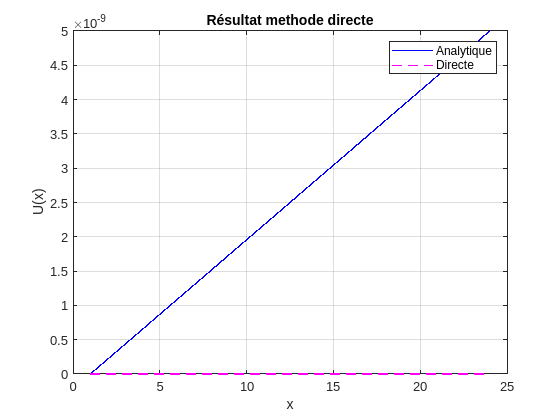

u_dual_concatenated = reshape(u_dual_precond, [], 1);
% Tracer les deux variables sur le même graphe
figure;
plot(x, U_ref, 'b-', 'LineWidth', 1);  % Trace y1 en bleu
hold on;  % Conserver le tracé actuel
plot(x, u_dual_concatenated, 'm--', 'LineWidth', 1); % Trace y2 en rouge en pointillé
xlabel('x');
ylabel('U(x)');
title('Résultat methode directe');
legend('Analytique', 'Directe');  % Légende pour les variables dépendantes
grid on;  % Afficher la grille

## Gradient conjugué

for k=1:m
    
   
    % Compute global matrix-vector product
    p_ass(:,k) = P' * Sd_ass * db_ass(:,k);  %p 

    % Compute optimal step
    dd = db_ass(:,k)' * p_ass(:,k);
    rr = r_ass' * db_ass(:,k);
    alpha = rr/dd;  %alpha

    % Compute iterate
    lb_ass = lb_ass + alpha * db_ass(:,k);

    % Compute residual
    r_ass = r_ass - alpha * p_ass(:,k);

    %Set
    z_ass = P * Sd_tilde_ass * r_ass;

    % Compute orthogonalization parameter
    s =zeros(ni,1);
    for j =1 : k
        rr_new = -z_ass' * p_ass(:,j);
        dd_new = db_ass(:,j)' * p_ass(:,j);
        beta(j) = rr_new / dd_new;
        s = s + beta(j) * db_ass(:,k);
    end
    % Update search direction
    db_ass(:,k+1) = z_ass + s;
    if(norm(r_ass)<tol)
        break
    end

end
disp(k);

     1



%Postprocessing
alb_conc = inv(G_ass' * Q * G_ass) * G_ass' * Q * (-bd_ass - Sd_ass * lb_ass) ;
 lb_conc = Ad_conc' * lb_ass;

 for sd = 1:ns
    if sd == 1  % encastrement -> i
        % Méthode par substitution
        i = 2:nn-1;     % on substitue ligne et colonne de u1
        b = nn;

        index_sp = 1;
        index_a = 1;
        index_rx = 1;
        index_ry = 0;
        index_lb = 1;

    elseif sd == ns % noeud libre -> i
        index_lb = index_lb + size(b,2);
        index_rx = index_rx + size(b,2);
        index_ry = index_ry + 1;

        i = 2:nn;
        b = 1;

        index_sp = n_bord;
        

    else
        index_lb = index_lb + size(b,2);
        index_rx = index_rx + size(b,2);
        index_ry = index_ry + 1;

        i = 2:nn-1;
        b = [1,nn];

        index_sp = 2 * (sd - 1);
        index_a = sd-1;
        
    end

    
    if sd == 1  % à cause du premier rigid body inexistant
        u_dual_precond(b,1,sd) = Sd_conc(index_sp:index_sp+size(b,2)-1,index_sp:index_sp+size(b,2)-1) ...
                            * (bp_conc(index_sp:index_sp+size(b,2)-1,1) + lb_conc(index_lb:index_lb+size(b,2)-1,1));
    else
        u_dual_precond(b,1,sd) = Sd_conc(index_sp:index_sp+size(b,2)-1,index_sp:index_sp+size(b,2)-1) ...
                            * (bp_conc(index_sp:index_sp+size(b,2)-1,1) + lb_conc(index_lb:index_lb+size(b,2)-1,1)) ...
                            + (Rb_conc(index_rx:index_rx+size(b,2)-1,index_ry) * alb_conc(index_ry,1));
    end

    u_dual_precond(i,1,sd) = K(i,i,sd) \ (F(i*sd)' - K(i,b,sd) * u_dual_precond(b,1,sd));
 end


## LATIN MONOSCALE

%Initialisation 
T = 10;
t = 1:T; 
m = 10; %A revoir
nn_sd = 2; %Nombre de noeud par sous-domaine 
K_sd = ones(nn_sd, nn_sd, ns);
k_sd = zeros(nn_sd, nn_sd, ns);
K_ass = zeros(nn_sd, nn_sd, ns);
sn= zeros(m+2, 1);
sn_chap = zeros(m+2, 1);


%Local
%Initialisation de K et k par sous-domaine, un element par sous domaine
K_sd(1,1,:) = -1;
K_sd(nn_sd, nn_sd,:) =-1;
k0 = (E * S / H) ;
K_sd = k0* K_sd; %Longueur uniforme entre sous-domaine


for i=1:ns
    kgauche = randi(100);% A revoir
    kdroite = randi(100);
    k_sd(1,1,i) = kgauche * k0;
    k_sd(nn_sd,nn_sd,i) = kdroite * k0;
end

%Assemblage des matrice K, k
for i=1:ns
    K_ass(:,:,i) = inv(K_sd(:,:,i) + k_sd(:,:,i));
end

%Initialisation de s_-1/2
sn(1) = 0;
sn_chap(1) = sn(1);

%Initialisation F_chap, W_chap
F_chap = zeros(ns+1,1);
Fn = zeros(nn_sd,ns);
W_chap = zeros(ns+1,1);
Wn = zeros(nn_sd,ns);
u_latin = zeros(nn_sd,ns);
F_conc = zeros(nn_sd, ns);
W_conc = zeros(nn_sd, ns);
mu = 0.8;


for i = 2: m+1
   %lineaire stage 
   for k=1: ns
    F_conc(:,k) = [-F_chap(k); F_chap(k+1)];
    W_conc(:,k) = [k_sd(1,1,k)*W_chap(k); k_sd(nn_sd,nn_sd,k) * W_chap(k+1)];
    Wn(:,k) = K_ass(:,:,k) * (F_conc(:,k) + W_conc(:,k) );
    u_latin = Wn;
    Fn(2,k) = F_chap(k) - k_sd(nn_sd,nn_sd,k) *(Wn(2,k) - W_chap(k));
    Fn(1,k) = F_chap(k) - k_sd(1,1,k) *(Wn(1,k) - W_chap(k));
   end

   %Relaxation
   %sn(i) = mu * sn(i) + (1- mu) * sn(i-1);

   %Local stage 
   %sn_chap(i) = sn(i);
   
   %Sous-domaine 1
   W_chap(1) = 0; %Car déplacement nul 
   F_chap(1) = Fn(2,1) - k_sd(1,1,1) * Wn(2,1);

   %Sous-domaine ns
   F_chap(ns+1) = Fd;
   W_chap(ns+1) = (1/k_sd(2,2,ns)) * (F_chap(ns+1) - Fn(2,ns)) + Wn(2,ns);

   %Perfect interFn(:,:,k) = F_chap(:,:,k) - k_sd(:,:,k) *(W(:,:,k) - W_chap(:,:,k));face
   for k=2:2:ns
    W_chap(k) = 1/2 *(Wn(1,k) + Wn(2, k)) - 1/(2 * k_sd(1,1,k)) * (Fn(1,k) + Fn(2,k));
    W_chap(k+1) = W_chap(k);
    F_chap(k) = Fn(2,k) + k_sd(1,1,k)* (W_chap(k) - Wn(2,k));
    F_chap(k+1) = -F_chap(k);
   end

   %Critère de convergence
    
end







    



## A faire

%% Méthode direct:
% - Fonctionne qu'avec un sous-domaine pour l'instant -> réussir à faire
% comme dans l'application
% 
%% Autres:
% - voir s'il ne faut pas enlever la substitution dans les i
% - Question 2.6: on devrait retrouver la matrice identité (si ca ne
%(Rb_conc(index_rx:index_rx+size(b,2)-1,index_ry) * alb_conc(index_ry,1));% fonctionne pas c'est à cause du pseudo-inverse qui n'est pas diagonale ?)
% (rcond pour voir le conditionnement)
% - Voir si c'est pas mieux de calculer qu'une seul fois inv(Kii), 
% - Faire une fonction dirichlet, qui résoud les déplacements interne à
% partir des déplacements bords.
% - Mettre en place vérification avec les assembleurs A_conc*A_conc'
% - Faire primal_problem sans utiliser Sp
% - faire penalty method et vérifier que rien ne change pour les operateurs
% - Comparer résultats analytiques avec primal approach
% - Etudier condtionnement de Sp
% - Paralléliser les produit matrice vecteur de chaque sous domaines
% - faire graphe de convergence des residus comme dans pcg()
% - vérifier résultat tmp
% - https://www.maxime-lefrancois.info/docs/stage2007.pdf